# PHASE 4 — Frequency-Domain Filtering for BrainWeb MRI

clear; clc; close all;

% Add paths
addpath(genpath("./src/filters"));
addpath(genpath("./src/utils"));

% Directories
dataDir = "./data/raw/";
outDir  = "./results/";
if ~exist(outDir,'dir'), mkdir(outDir); end

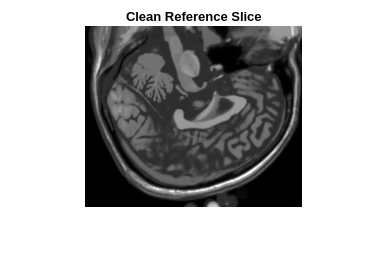

% Load Clean Slice

clean_vol = niftiread(fullfile(dataDir, "t1_icbm_normal_1mm_pn0_rf0.nii"));
slice_idx = round(size(clean_vol,3)/2);
clean = mat2gray(double(clean_vol(:,:,slice_idx)));

figure;
imshow(clean, []);
title("Clean Reference Slice");

% Noisy Files

noisy_list = [
    "t1_icbm_normal_1mm_pn3_rf0.nii"
    "t1_icbm_normal_1mm_pn5_rf0.nii"
    "t1_icbm_normal_1mm_pn9_rf0.nii"
];


Processing t1_icbm_normal_1mm_pn3_rf0.nii ...


Reading: ./data/raw/t1_icbm_normal_1mm_pn3_rf0.nii


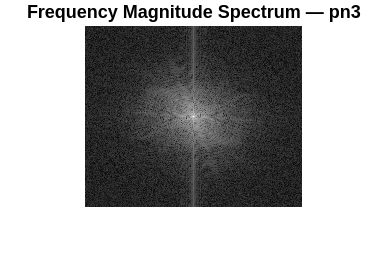

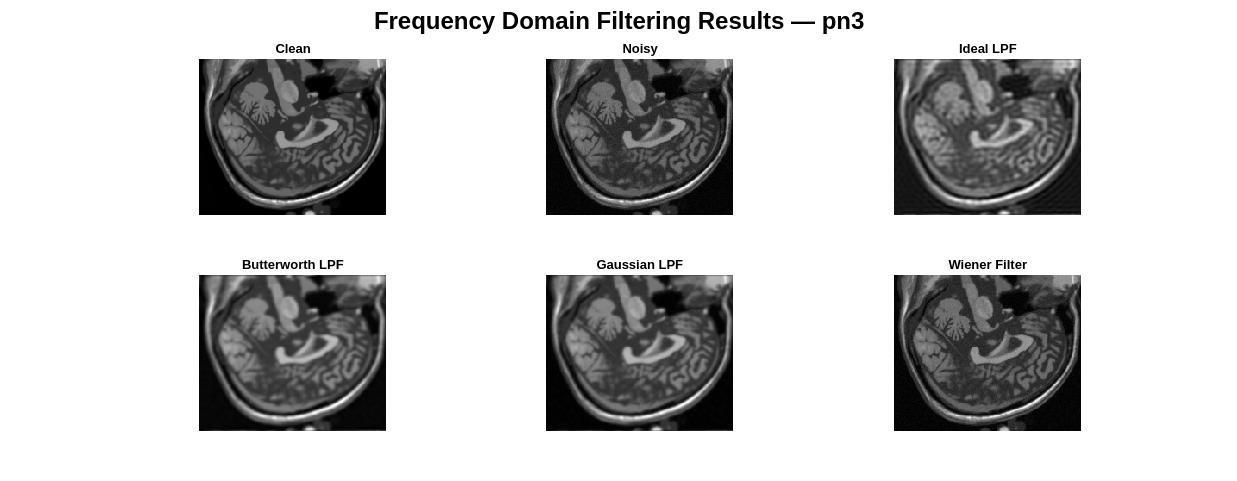

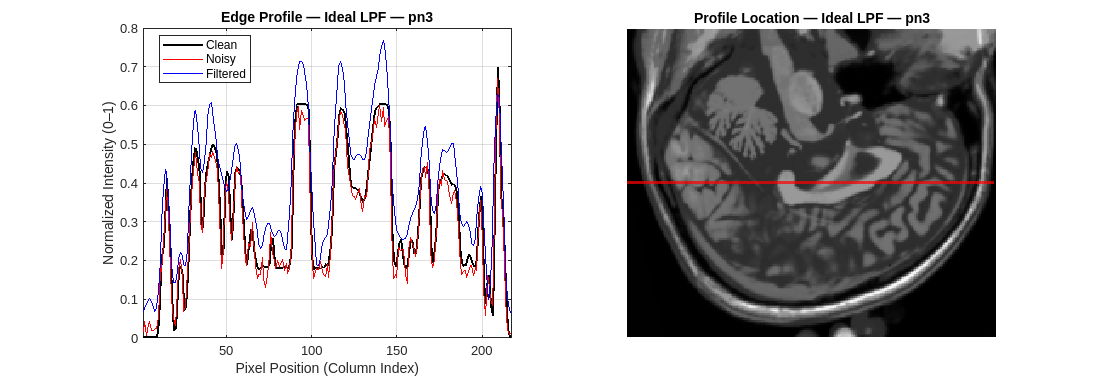

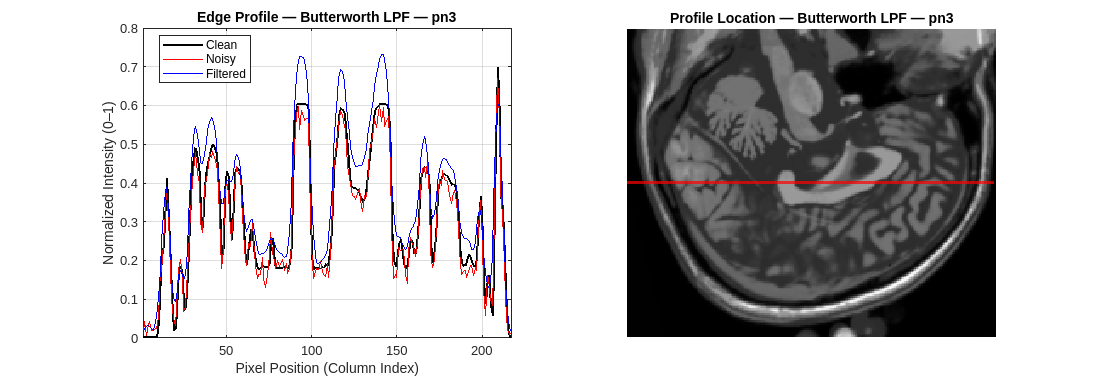

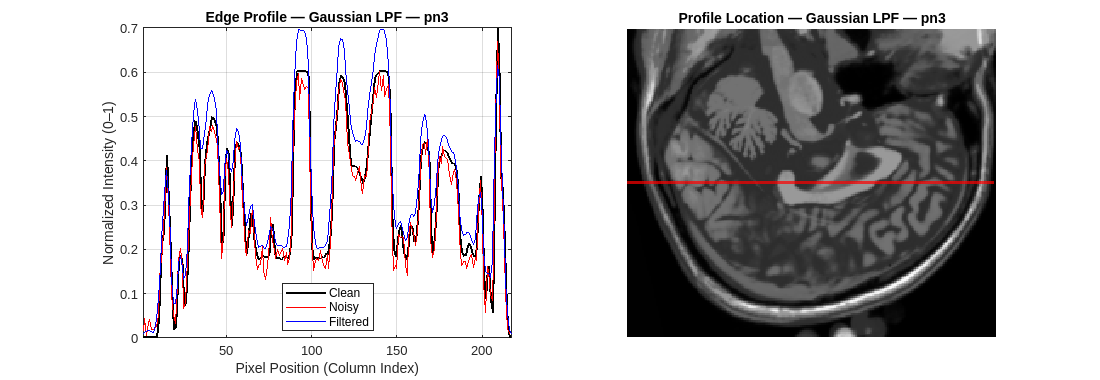

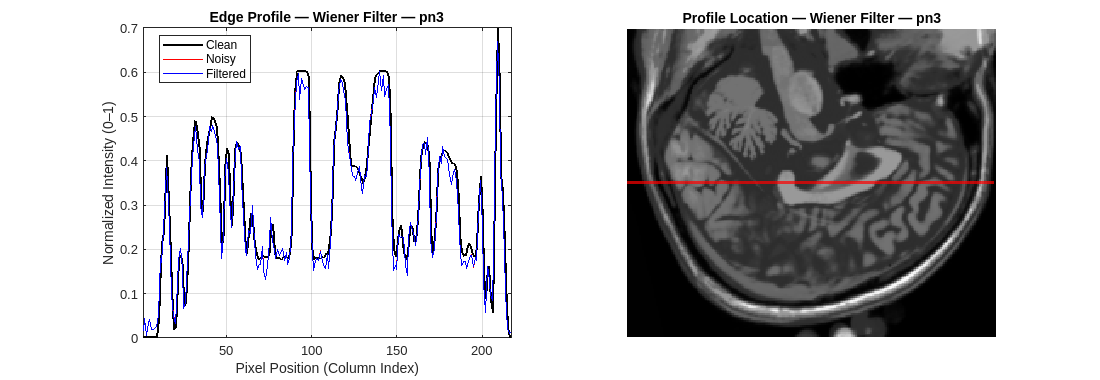


Processing t1_icbm_normal_1mm_pn5_rf0.nii ...


Reading: ./data/raw/t1_icbm_normal_1mm_pn5_rf0.nii


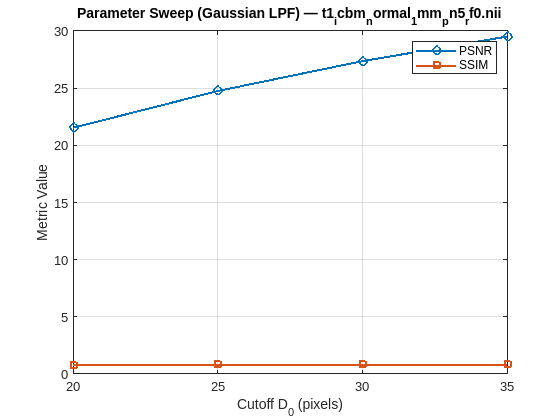

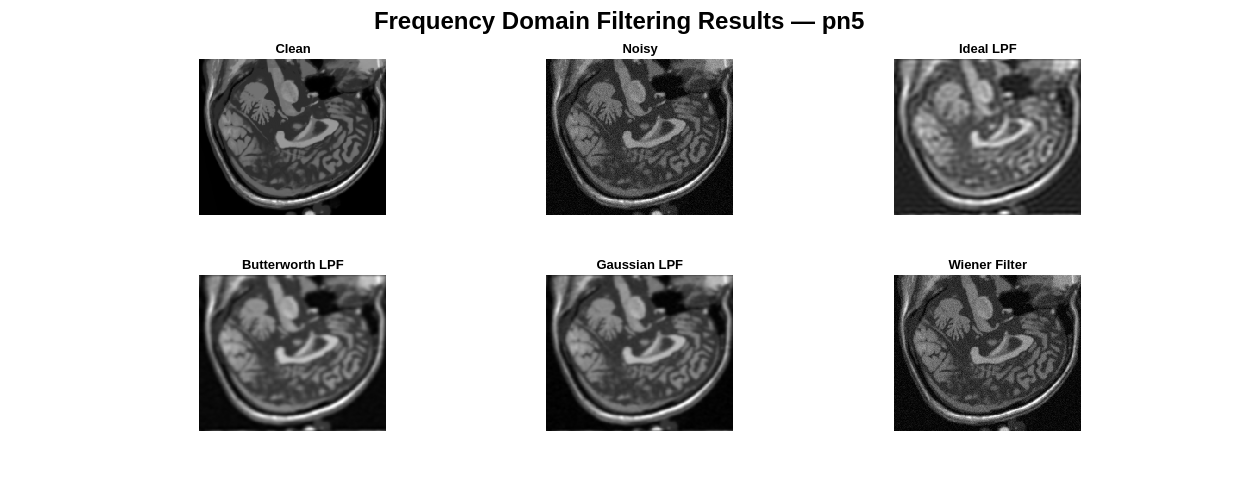

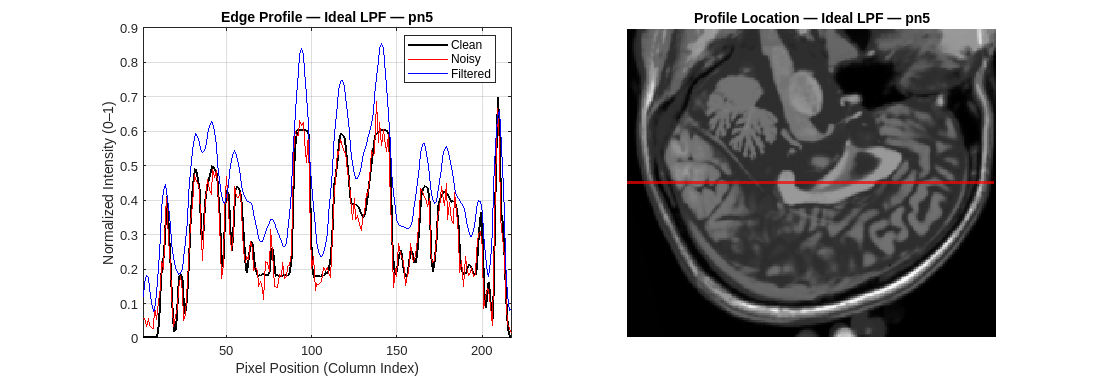

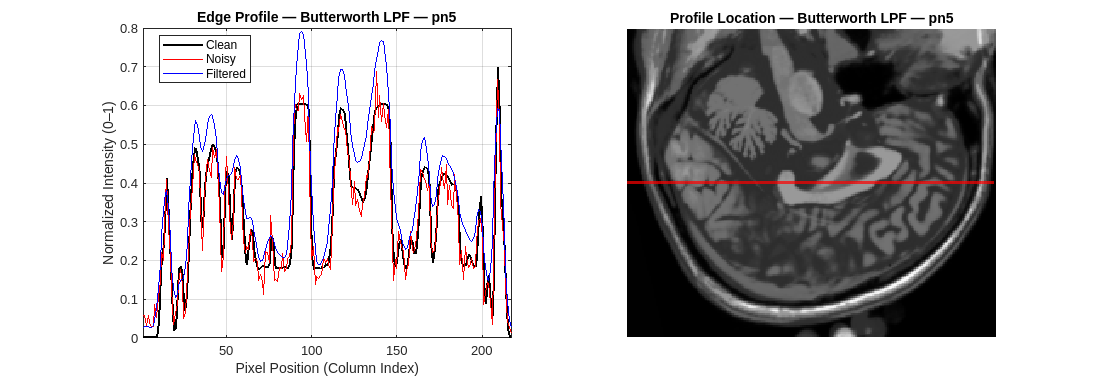

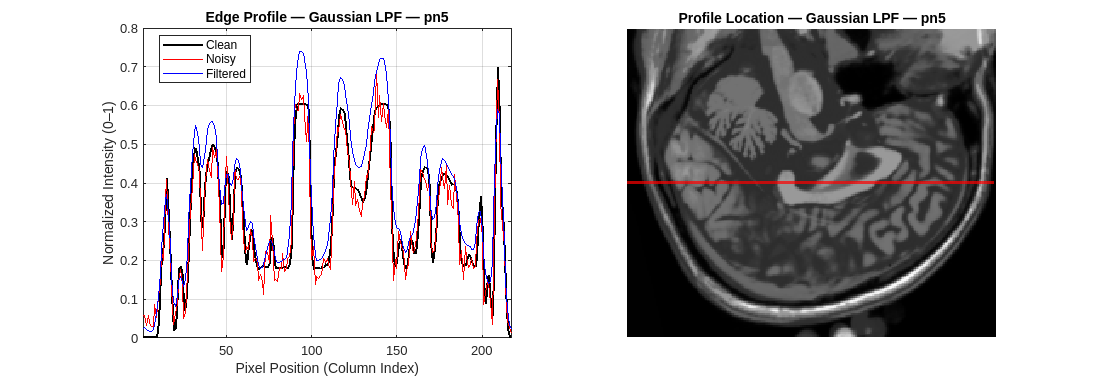

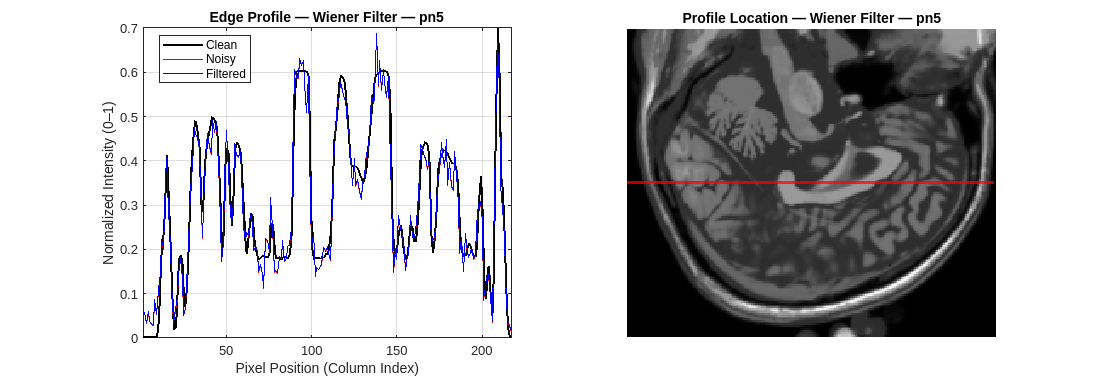


Processing t1_icbm_normal_1mm_pn9_rf0.nii ...


Reading: ./data/raw/t1_icbm_normal_1mm_pn9_rf0.nii


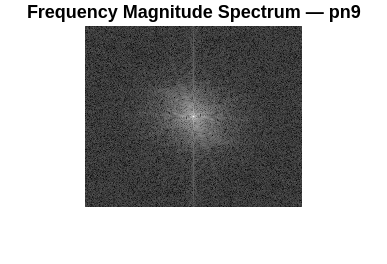

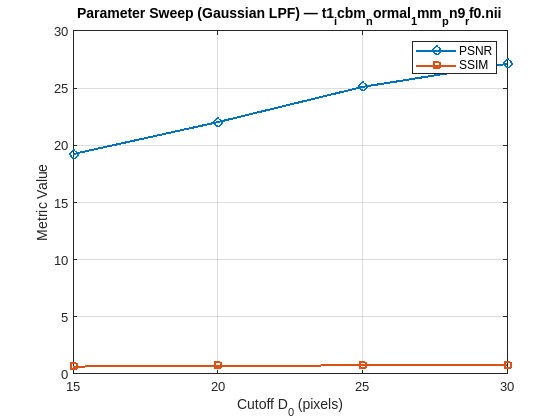

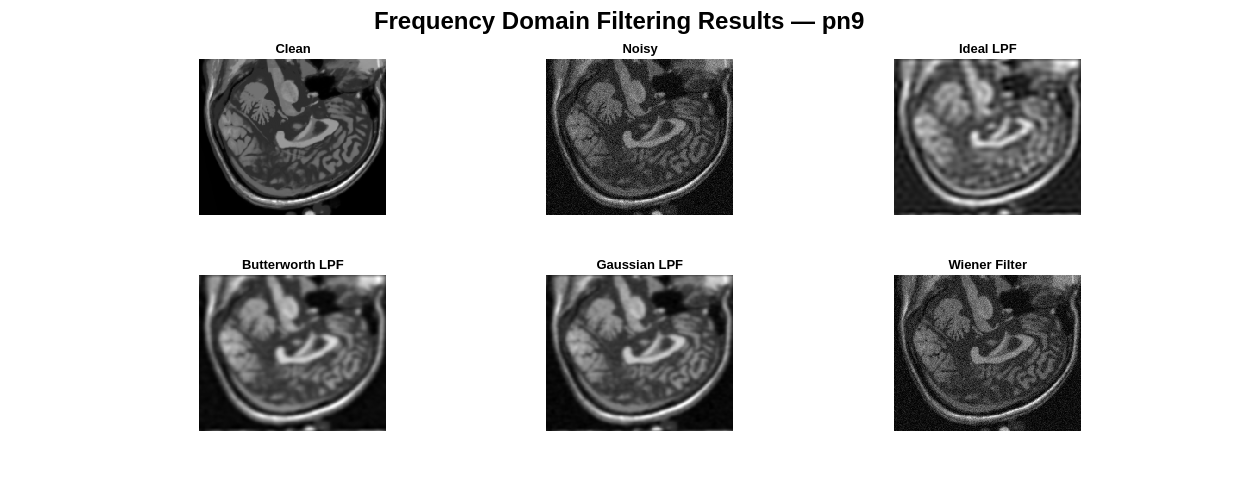

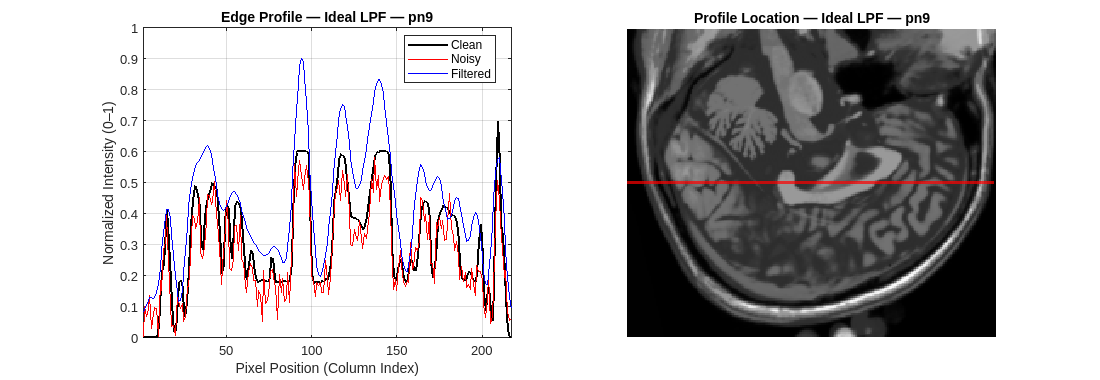

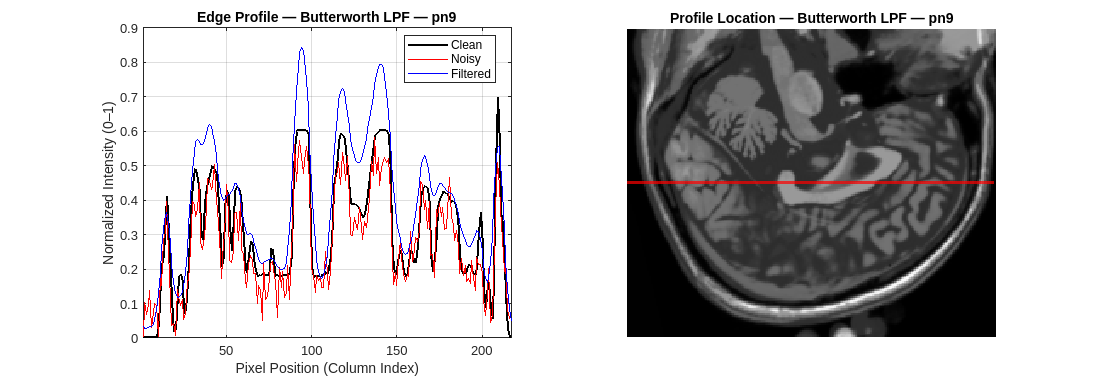

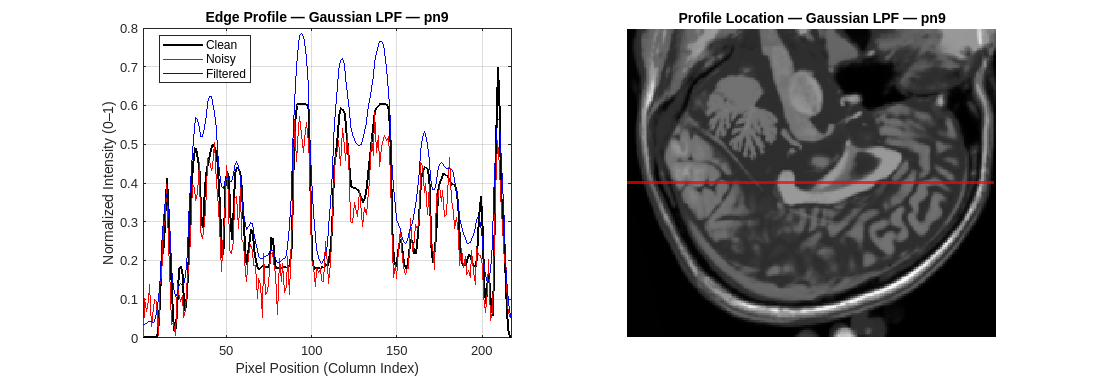

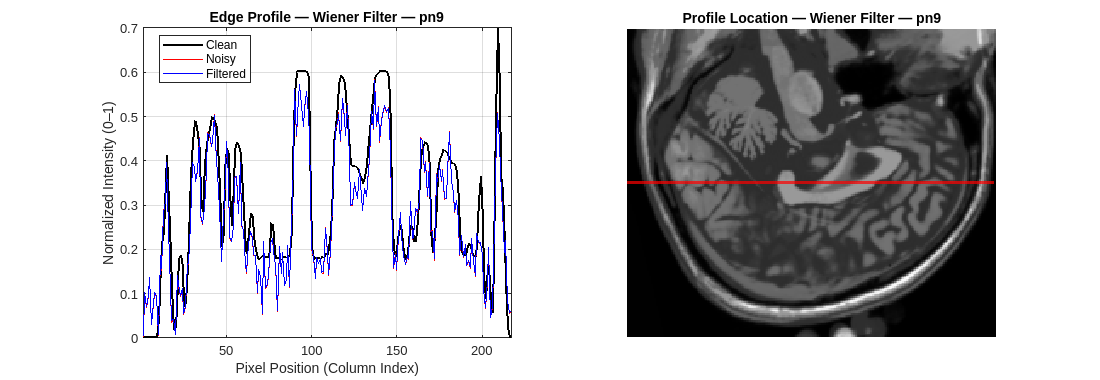

% MAIN LOOP
results = {};   

saveas_dir = fullfile(outDir, 'figures', 'phase4');
if ~exist(saveas_dir, 'dir'), mkdir(saveas_dir); end

% Precompute |S(u,v)|^2 from the clean slice (for Wiener filter)
S_clean  = fftshift(fft2(clean));
S_power  = abs(S_clean).^2;

for i = 1:length(noisy_list)

    % Extract filename 
    fname = noisy_list(i);    
    fname = char(fname);      
    fprintf("\nProcessing %s ...\n", fname);

    % Load noisy slice
    fpath = fullfile(dataDir, fname);
    disp("Reading: " + string(fpath));

    vol_noisy = niftiread(fpath);
    noisy = mat2gray(double(vol_noisy(:,:,slice_idx)));

    % FFT of noisy image
    F = fftshift(fft2(noisy));

    % Save magnitude spectrum
    show_freq_spectrum(F, fname, fullfile(saveas_dir, fname + "_freq.png"));

    % Distance grid
    [M,N] = size(noisy);
    [u,v] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
    D = sqrt(u.^2 + v.^2);

    % Parameter Sweep for Gaussian LPF
    if strcmp(fname, "t1_icbm_normal_1mm_pn3_rf0.nii")
        D0_list = [25 30 35 40];
    elseif strcmp(fname, "t1_icbm_normal_1mm_pn5_rf0.nii")
        D0_list = [20 25 30 35];
    else
        D0_list = [15 20 25 30];
    end

    psnr_vals = zeros(size(D0_list));
    ssim_vals = zeros(size(D0_list));

    for k = 1:length(D0_list)
        D0 = D0_list(k);

        H = gaussian_lpf(D, D0);
        img = mat2gray(real(ifft2(ifftshift(H .* F))));

        [psnr_vals(k), ssim_vals(k)] = compute_metrics(img, clean);
    end

    % Sweep plot
    figure;
    plot(D0_list, psnr_vals,'-o','LineWidth',1.5); hold on;
    plot(D0_list, ssim_vals,'-s','LineWidth',1.5);
    xlabel("Cutoff D_0 (pixels)");
    ylabel("Metric Value");
    legend("PSNR","SSIM");
    title("Parameter Sweep (Gaussian LPF) — " + string(fname));
    grid on;
    saveas(gcf, fullfile(saveas_dir, fname + "_sweep.png"));

    % Choose middle cutoff
    D0 = D0_list(round(end/2));

    % Estimate noise variance for Wiener filter
    noise_residual = noisy - clean;      
    noise_var = var(noise_residual(:));  

    % Apply All Filters
    H_ideal  = ideal_lpf(D, D0);
    H_butt   = butterworth_lpf(D, D0, 2);
    H_gauss  = gaussian_lpf(D, D0);
    H_wiener = wiener_filter(S_power, noise_var);   % NEW

    ideal_img  = mat2gray(real(ifft2(ifftshift(H_ideal  .* F))));
    butt_img   = mat2gray(real(ifft2(ifftshift(H_butt   .* F))));
    gauss_img  = mat2gray(real(ifft2(ifftshift(H_gauss  .* F))));
    wiener_img = mat2gray(real(ifft2(ifftshift(H_wiener .* F))));

    % Extract noise level (pn3, pn5, pn9)
    parts = split(fname, "_");
    pn_level = erase(parts{5}, ".nii");

    % Summary Visualization
    fig = figure('Position',[200 200 1800 700]);

    % A big title for the whole figure
    sgtitle("Frequency Domain Filtering Results — " + pn_level, ...
            'FontSize', 18, 'FontWeight','bold');

    subplot(2,3,1), imshow(clean),       title("Clean");
    subplot(2,3,2), imshow(noisy),       title("Noisy");
    subplot(2,3,3), imshow(ideal_img),   title("Ideal LPF");
    subplot(2,3,4), imshow(butt_img),    title("Butterworth LPF");
    subplot(2,3,5), imshow(gauss_img),   title("Gaussian LPF");
    subplot(2,3,6), imshow(wiener_img),  title("Wiener Filter");

    saveas(fig, fullfile(saveas_dir, fname + "_summary.png"));

    % Compute Metrics
    [ps_i, ss_i] = compute_metrics(ideal_img,  clean);
    [ps_b, ss_b] = compute_metrics(butt_img,   clean);
    [ps_g, ss_g] = compute_metrics(gauss_img,  clean);
    [ps_w, ss_w] = compute_metrics(wiener_img, clean);

    results = [results;
        {fname, "Ideal LPF",        ps_i, ss_i};
        {fname, "Butterworth LPF",  ps_b, ss_b};
        {fname, "Gaussian LPF",     ps_g, ss_g};
        {fname, "Wiener Filter",    ps_w, ss_w};
    ];

    % Edge Preservation Analysis
    edge_profile(clean, noisy, ideal_img,  "Ideal LPF",        fname, fullfile(saveas_dir, fname + "_edge_ideal.png"));
    edge_profile(clean, noisy, butt_img,   "Butterworth LPF",  fname, fullfile(saveas_dir, fname + "_edge_butterworth.png"));
    edge_profile(clean, noisy, gauss_img,  "Gaussian LPF",     fname, fullfile(saveas_dir, fname + "_edge_gaussian.png"));
    edge_profile(clean, noisy, wiener_img, "Wiener Filter",    fname, fullfile(saveas_dir, fname + "_edge_wiener.png"));

end

% Save Metrics to CSV

metricsDir = fullfile(outDir, 'metrics');
if ~exist(metricsDir, 'dir')
    mkdir(metricsDir);
end

T = cell2table(results, ...
    'VariableNames', {'NoiseFile','Filter','PSNR','SSIM'});

% Display table
T 

T = 12×4 table
                NoiseFile                      Filter           PSNR      SSIM  
    __________________________________    _________________    ______    _______

    {'t1_icbm_normal_1mm_pn3_rf0.nii'}    "Ideal LPF"          20.718    0.67074
    {'t1_icbm_normal_1mm_pn3_rf0.nii'}    "Butterworth LPF"     24.07    0.77851
    {'t1_icbm_normal_1mm_pn3_rf0.nii'}    "Gaussian LPF"       26.254    0.85827
    {'t1_icbm_normal_1mm_pn3_rf0.nii'}    "Wiener Filter"      33.197    0.83603
    {'t1_icbm_normal_1mm_pn5_rf0.nii'}    "Ideal LPF"          17.254    0.58115
    {'t1_icbm_normal_1mm_pn5_rf0.nii'}    "Butterworth LPF"    22.179     0.7287
    {'t1_icbm_normal_1mm_pn5_rf0.nii'}    "Gaussian LPF"       24.754    0.80981
    {'t1_icbm_normal_1mm_pn5_rf0.nii'}    "Wiener Filter"      29.914    0.73739
    {'t1_icbm_normal_1mm_pn9_rf0.nii'}

% Save CSV
csvPath = fullfile(metricsDir, 'phase4_metrics.csv');
writetable(T, csvPath);

disp("PHASE 4 COMPLETE — Results saved to:");

PHASE 4 COMPLETE — Results saved to:


disp(csvPath);

./results/metrics/phase4_metrics.csv
